syms t s
R=10

R = 10

C=0.001

C = 1.0000e-03

HS=1/(s+R/C)

$$HS = \frac{1}{s+10000}$$

ht=ilaplace(HS)

$$ht = {\mathrm{e}}^{-10000\,t}$$

xt=2*exp(-100*t)

$$xt = 2\,{\mathrm{e}}^{-100\,t}$$

XS=laplace(xt)

$$XS = \frac{2}{s+100}$$

YS=HS*XS

$$YS = \frac{2}{\left(s+100\right)\,\left(s+10000\right)}$$

yt=ilaplace(YS)

$$yt = \frac{{\mathrm{e}}^{-100\,t}}{4950}-\frac{{\mathrm{e}}^{-10000\,t}}{4950}$$

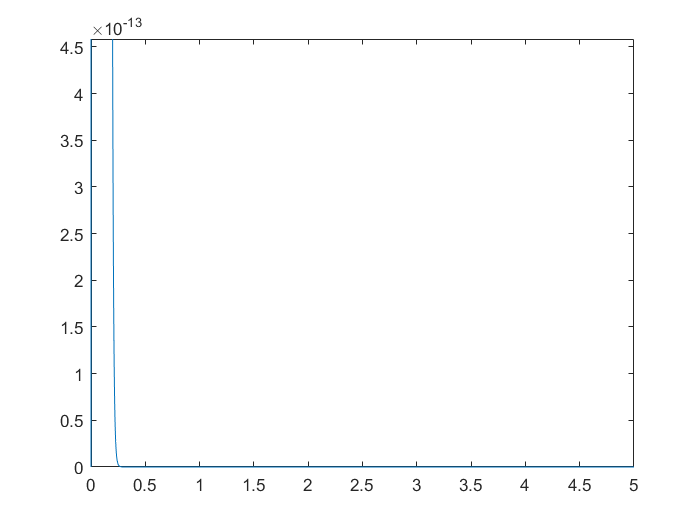

yt=yt*heaviside(t)
fplot(yt)